% --- MAIN SCRIPT FOR NONLINEAR BEAM FEA ---
% Based on Euler-Bernoulli theory with von Karman nonlinearity
% Solved with a single Hermite element using Newton-Raphson method.

% clear; clc; close all;

%% 1a. Load pre-compiled symbolic functions
if ~exist('beam_functions.mat', 'file')
    error('File beam_functions.mat not found. Please run generate_beam_functions.m first.');
end
load('beam_functions.mat'); % This loads f_int_handle and K_T_handle


%% 1. Define Beam and Material Properties
L = 1.0;          % Length of the beam (m)
E = 210e9;        % Young's Modulus (Pa) for steel
b = 0.05;         % Cross-section width (m)
h = 0.05;         % Cross-section height (m)
A = b * h;        % Area
I = b * h^3 / 12; % Moment of inertia

%% 2. Define FE Model and Analysis Parameters
total_dof = 6; % u1, w1, theta1, u2, w2, theta2

% Boundary Conditions for Cantilever Beam
% Node 1 is fixed (DOFs 1, 2, 3)
% Node 2 is free (DOFs 4, 5, 6)
dof_prescribed = [1, 2, 3];
dof_free = [4, 5, 6];

% Analysis Control
P_max = 5e6;              % Maximum transverse load at the tip (N)
num_steps = 20;           % Number of load increments
load_steps = linspace(P_max/num_steps, P_max, num_steps);

max_iter = 20;            % Max iterations per load step
tolerance = 1e-6;         % Convergence tolerance for residual norm

%% 3. Initialize Variables for History Tracking
U = zeros(total_dof, 1);  % Global displacement vector
U_history = zeros(length(dof_free), num_steps); % Store free DOF results
F_ext_total = zeros(total_dof, 1);

fprintf('--- Nonlinear FE Analysis of a Cantilever Beam ---\n');

--- Nonlinear FE Analysis of a Cantilever Beam ---


fprintf('Load Steps: %d, Max Load: %.2e N\n\n', num_steps, P_max);

Load Steps: 20, Max Load: 5.00e+06 N




%% 4. Load Increment Loop
for step = 1:num_steps
    
    current_load = load_steps(step);
    F_ext_total(5) = current_load; % Apply vertical load at node 2, DOF 5
    
    fprintf('Load Step %d/%d, Applied Load = %.2e N\n', step, num_steps, current_load);
    
    % --- Newton-Raphson Iteration Loop ---
    for iter = 1:max_iter
        
        % Calculate internal force and tangent stiffness for the single element
        [f_int, K_T] = element_routine_beam_fast(L, E, A, I, U, f_int_handle, K_T_handle);
        
        % Calculate the residual (out-of-balance) force
        R = F_ext_total - f_int;
        
        % Check for convergence on free DOFs
        norm_R = norm(R(dof_free));
        fprintf('  Iteration %d: Residual Norm = %.4e\n', iter, norm_R);
        
        if norm_R < tolerance
            fprintf('  Convergence achieved in %d iterations.\n\n', iter);
            break;
        end
        
        if iter == max_iter
            warning('Max iterations reached without convergence at load step %d', step);
            break;
        end
        
        % Solve for displacement increment
        K_T_reduced = K_T(dof_free, dof_free);
        R_reduced = R(dof_free);
        
        delta_U_reduced = K_T_reduced \ R_reduced;
        
        % Update the total displacement vector
        U(dof_free) = U(dof_free) + delta_U_reduced;
        
    end
    
    % Store the converged displacements for plotting
    U_history(:, step) = U(dof_free);
    
end

Load Step 1/20, Applied Load = 2.50e+05 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 2.5635e+08
  Iteration 3: Residual Norm = 2.5885e+07
  Iteration 4: Residual Norm = 1.8609e+07
  Iteration 5: Residual Norm = 5.9035e+06
  Iteration 6: Residual Norm = 3.0815e+06
  Iteration 7: Residual Norm = 1.2001e+06
  Iteration 8: Residual Norm = 4.2942e+05
  Iteration 9: Residual Norm = 7.9747e+04
  Iteration 10: Residual Norm = 3.4483e+03
  Iteration 11: Residual Norm = 6.2618e+00
  Iteration 12: Residual Norm = 2.1063e-05
  Iteration 13: Residual Norm = 4.7397e-10


  Convergence achieved in 13 iterations.



Load Step 2/20, Applied Load = 5.00e+05 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 8.1701e+05
  Iteration 3: Residual Norm = 3.5917e+04
  Iteration 4: Residual Norm = 8.9297e+02
  Iteration 5: Residual Norm = 1.7029e-01
  Iteration 6: Residual Norm = 8.7244e-09


  Convergence achieved in 6 iterations.



Load Step 3/20, Applied Load = 7.50e+05 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 3.1346e+05
  Iteration 3: Residual Norm = 5.9840e+03
  Iteration 4: Residual Norm = 1.4643e+01
  Iteration 5: Residual Norm = 3.6624e-05
  Iteration 6: Residual Norm = 1.7899e-09


  Convergence achieved in 6 iterations.



Load Step 4/20, Applied Load = 1.00e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 1.8105e+05
  Iteration 3: Residual Norm = 1.8582e+03
  Iteration 4: Residual Norm = 1.0440e+00
  Iteration 5: Residual Norm = 1.5128e-07


  Convergence achieved in 5 iterations.



Load Step 5/20, Applied Load = 1.25e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 1.2334e+05
  Iteration 3: Residual Norm = 7.8483e+02
  Iteration 4: Residual Norm = 1.4998e-01
  Iteration 5: Residual Norm = 3.6771e-09


  Convergence achieved in 5 iterations.



Load Step 6/20, Applied Load = 1.50e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 9.1887e+04
  Iteration 3: Residual Norm = 3.9737e+02
  Iteration 4: Residual Norm = 3.2408e-02
  Iteration 5: Residual Norm = 1.2860e-08


  Convergence achieved in 5 iterations.



Load Step 7/20, Applied Load = 1.75e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 7.2400e+04
  Iteration 3: Residual Norm = 2.2664e+02
  Iteration 4: Residual Norm = 9.1452e-03
  Iteration 5: Residual Norm = 7.5230e-09


  Convergence achieved in 5 iterations.



Load Step 8/20, Applied Load = 2.00e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 5.9278e+04
  Iteration 3: Residual Norm = 1.4059e+02
  Iteration 4: Residual Norm = 3.1146e-03
  Iteration 5: Residual Norm = 3.3354e-09


  Convergence achieved in 5 iterations.



Load Step 9/20, Applied Load = 2.25e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 4.9908e+04
  Iteration 3: Residual Norm = 9.2833e+01
  Iteration 4: Residual Norm = 1.2197e-03
  Iteration 5: Residual Norm = 3.7792e-09


  Convergence achieved in 5 iterations.



Load Step 10/20, Applied Load = 2.50e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 4.2919e+04
  Iteration 3: Residual Norm = 6.4320e+01
  Iteration 4: Residual Norm = 5.3199e-04
  Iteration 5: Residual Norm = 4.2167e-09


  Convergence achieved in 5 iterations.



Load Step 11/20, Applied Load = 2.75e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 3.7527e+04
  Iteration 3: Residual Norm = 4.6302e+01
  Iteration 4: Residual Norm = 2.5277e-04
  Iteration 5: Residual Norm = 7.1002e-09


  Convergence achieved in 5 iterations.



Load Step 12/20, Applied Load = 3.00e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 3.3256e+04
  Iteration 3: Residual Norm = 3.4384e+01
  Iteration 4: Residual Norm = 1.2877e-04
  Iteration 5: Residual Norm = 2.3906e-09


  Convergence achieved in 5 iterations.



Load Step 13/20, Applied Load = 3.25e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 2.9797e+04
  Iteration 3: Residual Norm = 2.6200e+01
  Iteration 4: Residual Norm = 6.9507e-05
  Iteration 5: Residual Norm = 9.5570e-09


  Convergence achieved in 5 iterations.



Load Step 14/20, Applied Load = 3.50e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 2.6945e+04
  Iteration 3: Residual Norm = 2.0402e+01
  Iteration 4: Residual Norm = 3.9393e-05
  Iteration 5: Residual Norm = 7.2323e-09


  Convergence achieved in 5 iterations.



Load Step 15/20, Applied Load = 3.75e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 2.4557e+04
  Iteration 3: Residual Norm = 1.6185e+01
  Iteration 4: Residual Norm = 2.3260e-05
  Iteration 5: Residual Norm = 9.4113e-09


  Convergence achieved in 5 iterations.



Load Step 16/20, Applied Load = 4.00e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 2.2532e+04
  Iteration 3: Residual Norm = 1.3046e+01
  Iteration 4: Residual Norm = 1.4249e-05
  Iteration 5: Residual Norm = 2.4279e-08


  Convergence achieved in 5 iterations.



Load Step 17/20, Applied Load = 4.25e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 2.0794e+04
  Iteration 3: Residual Norm = 1.0664e+01
  Iteration 4: Residual Norm = 9.0006e-06
  Iteration 5: Residual Norm = 7.9602e-09


  Convergence achieved in 5 iterations.



Load Step 18/20, Applied Load = 4.50e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 1.9289e+04
  Iteration 3: Residual Norm = 8.8240e+00
  Iteration 4: Residual Norm = 5.8442e-06
  Iteration 5: Residual Norm = 4.8274e-09


  Convergence achieved in 5 iterations.



Load Step 19/20, Applied Load = 4.75e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 1.7974e+04
  Iteration 3: Residual Norm = 7.3815e+00
  Iteration 4: Residual Norm = 3.9011e-06
  Iteration 5: Residual Norm = 8.6468e-09


  Convergence achieved in 5 iterations.



Load Step 20/20, Applied Load = 5.00e+06 N


  Iteration 1: Residual Norm = 2.5000e+05
  Iteration 2: Residual Norm = 1.6815e+04
  Iteration 3: Residual Norm = 6.2351e+00
  Iteration 4: Residual Norm = 2.6438e-06
  Iteration 5: Residual Norm = 1.5174e-08


  Convergence achieved in 5 iterations.



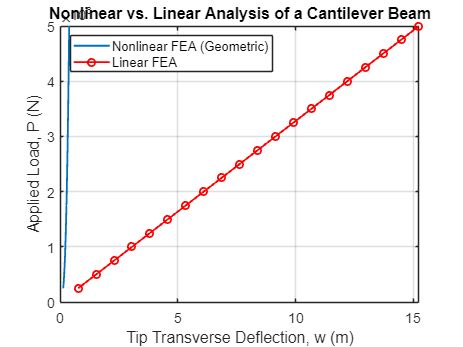


%% 5. Post-Processing and Plotting
figure('Name', 'Nonlinear Load-Deflection Curve');
plot(U_history(2,:), load_steps, '-', 'LineWidth', 1.5);
hold on;

% For comparison, plot the linear solution
w_linear = (load_steps * L^3) / (3 * E * I);
plot(w_linear, load_steps, '-or', 'LineWidth', 1.5);

grid on;
title('Nonlinear vs. Linear Analysis of a Cantilever Beam');
xlabel('Tip Transverse Deflection, w (m)');
ylabel('Applied Load, P (N)');
legend('Nonlinear FEA (Geometric)', 'Linear FEA', 'Location', 'NorthWest');
set(gca, 'FontSize', 12);


fprintf('--- Analysis Complete ---\n');

--- Analysis Complete ---
